# Template of Manipulator Short project: Skull tumor surgery

Authors: 

Pablo Montón Gimeno

Mauro García Lorenzo

Team:  L

Link: https://drive.matlab.com/sharing/205cab5a-35f7-4f76-98c6-daea26e86ecd

Shared Link with the teacher: 

I spect: 1) Pdf file, 2) Videos demostrating your successful task and your mlx file.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

**Expected results**

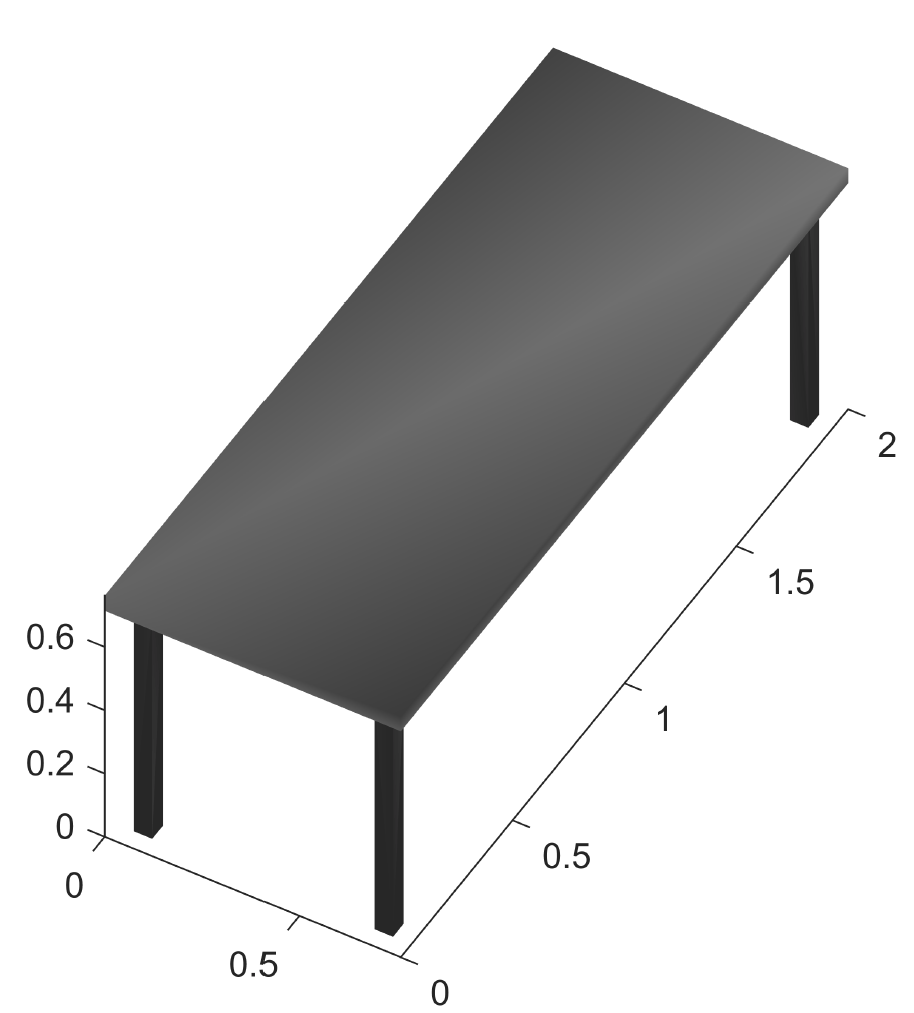

## put your code Here

clear
clf
minXMesa = 0

minXMesa = 0

minYMesa = 0

minYMesa = 0

maxXMesa = 2

maxXMesa = 2

maxYMesa = 0.75

maxYMesa = 0.7500

minZMesa = 0.5

minZMesa = 0.5000

maxZMesa = 0.6

maxZMesa = 0.6000

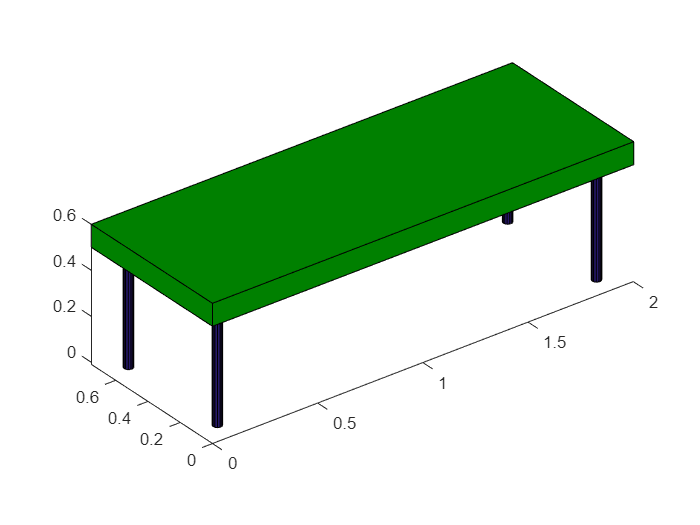

v = [minXMesa minYMesa minZMesa; minXMesa maxYMesa minZMesa; maxXMesa maxYMesa minZMesa; maxXMesa minYMesa minZMesa;minXMesa minYMesa maxZMesa; minXMesa maxYMesa maxZMesa; maxXMesa maxYMesa maxZMesa; maxXMesa minYMesa maxZMesa];
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
view(3)
patch('Faces',f,'Vertices',v,'FaceColor',[0 0.5 0])
r = 0.02;
[X,Y,Z] = cylinder(r);
h = 0.6;
Z = Z*h-0.01;
hold on
surf(X+0.1,Y+0.1,Z)
surf(X+0.1,Y+0.65,Z)
surf(X+1.9,Y+0.1,Z)
surf(X+1.9,Y+0.65,Z)
axis equal

### 3D model of a human body 

Situate the human model on the operating table. 

**Expected results**

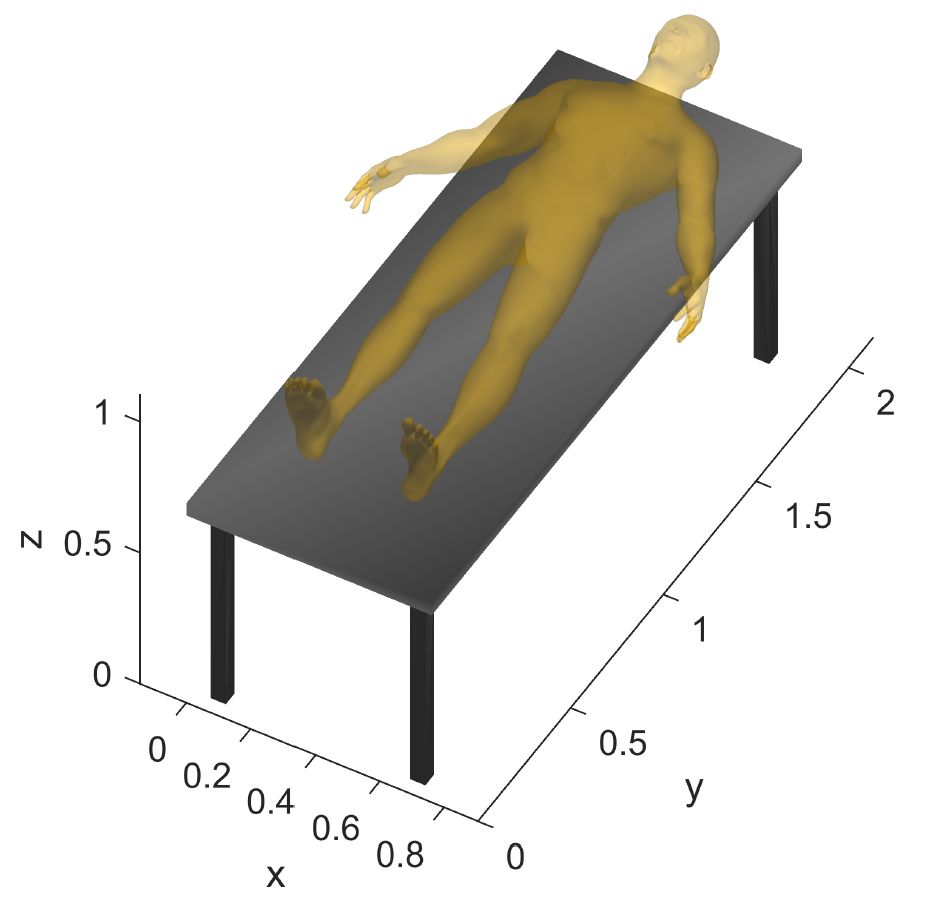

## put your code Here


load('F_V_HumanBody.mat')
view(3)
Vh(:,4) = 1;
Vh1 = transl(0.45,0.375,0.77)*trotz(-pi/2)*trotx(-pi/2)*Vh'

Vh1 =     1.7610    1.7649    1.7738    1.7706    1.7789    1.7786    1.7805    1.7844    1.7881    1.7919    1.7961    1.8000    1.7864    1.7948    1.7972    1.8035    1.8068    1.8125    1.8165    1.8214    1.8262    1.8301    1.8359    1.8312    1.8206    1.8419    1.8245    1.8316    1.8383    1.8167    1.8452    1.8084    1.8042    1.8121    1.8100    1.7996    1.7909    1.7894    1.8019    1.7879    1.7792    1.7787    1.7799    1.8131    1.8159    1.8039    1.7922    1.7693    1.7580    1.7589
    0.4893    0.5018    0.4941    0.4857    0.4896    0.4833    0.4987    0.4912    0.5016    0.4930    0.5037    0.4948    0.4831    0.4840    0.4743    0.4853    0.4753    0.4869    0.4768    0.4889    0.4789    0.4912    0.4814    0.4684    0.4663    0.4710    0.5003    0.5027    0.4941    0.4983    0.4846    0.4965    0.5054    0.5068    0.4649    0.4640    0.4530    0.4637    0.4532    0.4739    0.4641    0.4743    0.4533    0.4541    0.4432    0.4425    0.4422    0.4759    0.4667   

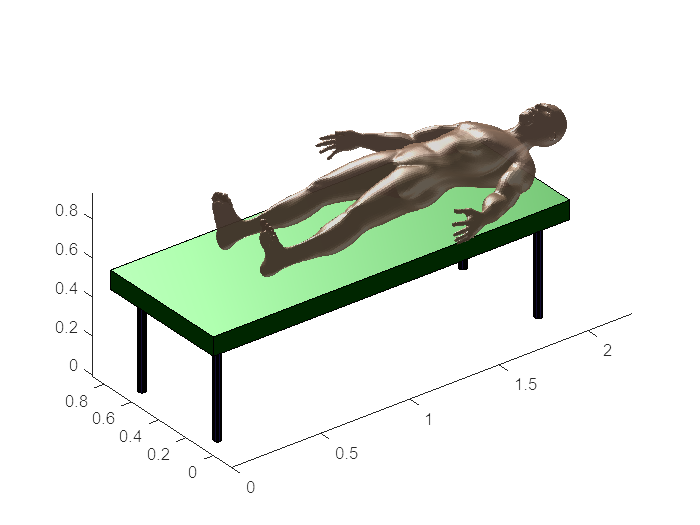

patch('Vertices',Vh1(1:3,:)','Faces',Fh,'FaceColor', [0.82 0.64 0.52], 'EdgeColor' , 'none', 'FaceAlpha', 0.8)
axis equal
light('Position',[0.2 0.6 0.4]);
view(3)

### Fiducials

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

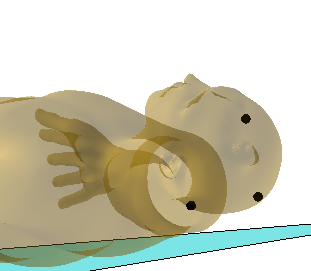

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images, Visit: https://www.imaios.com/en/Imaios-Dicom-Viewer#!

Use a container Box of the skull  to infer the Image Reference Frame {I}

See:  6_Plot_Box_Cone.mlx and 7_Help_Image_RF_Containig_Box.fig to inspire yourselt 

**Expected results**

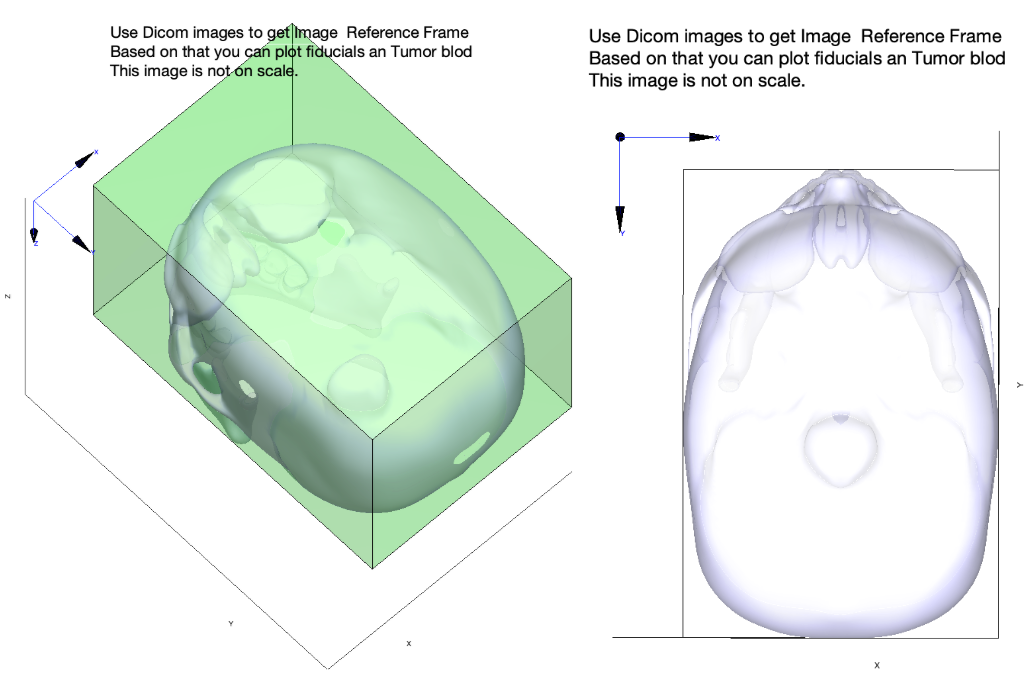

## put your code Here

clear
clf
load('F_V_Skull.mat')
view(3)
Vs(:,4) = 1;
Vs2 = trotz(pi) * Vs';
Vs2 = Vs2(1:3,:)'

Vs2 =     0.0127    0.1141    0.0085
    0.0097    0.1154    0.0082
    0.0094    0.1149    0.0110
    0.0124    0.1136    0.0112
    0.0065    0.1165    0.0080
    0.0063    0.1159    0.0108
    0.0061    0.1152    0.0140
    0.0092    0.1142    0.0142
    0.0122    0.1130    0.0143
    0.0033    0.1172    0.0078


patch('Vertices',Vs2,'Faces',Fs,'FaceColor', [0.5 0.5 0.5], 'EdgeColor' , 'none','FaceAlpha', 0.5)
%,'FaceColor', [0.5 0.5 0.5], 'EdgeColor' , 'none','FaceAlpha', 0.7
axis equal
max = max(Vs2)

max =     0.0765    0.1194    0.2127


maxX = max(1)

maxX = 0.0765

maxY = max(2)

maxY = 0.1194

maxZ = max(3)

maxZ = 0.2127

minX = min(1)

minX = 1

minY = min(2)

minY = 2

minZ = 0.072

minZ = 0.0720

v= [minX minY minZ;maxX minY minZ;maxX maxY minZ;minX maxY minZ;minX minY maxZ;maxX minY maxZ;maxX maxY maxZ;minX maxY maxZ]

v =     1.0000    2.0000    0.0720
    0.0765    2.0000    0.0720
    0.0765    0.1194    0.0720
    1.0000    0.1194    0.0720
    1.0000    2.0000    0.2127
    0.0765    2.0000    0.2127
    0.0765    0.1194    0.2127
    1.0000    0.1194    0.2127


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


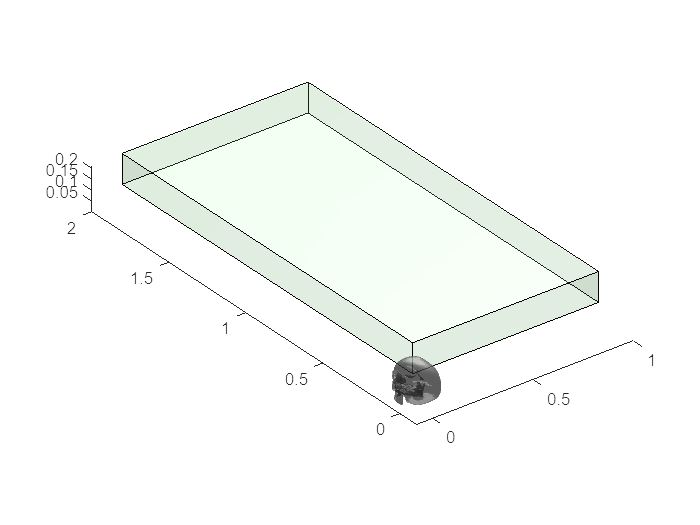

patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)
light('Position',[1 1 1]);

altura = maxZ-minZ

altura = 0.1407

ancho = maxY-minY

ancho = -1.8806

hondo=maxX-minX

hondo = -0.9235

### Fiducials wrt {I}

Use the Dicom images to place the fiducial relative to Image Reference Frame {I}.

See: 5_Skull_pose_estimation.mlx and use the skull to make the exercise.

**Expected results**

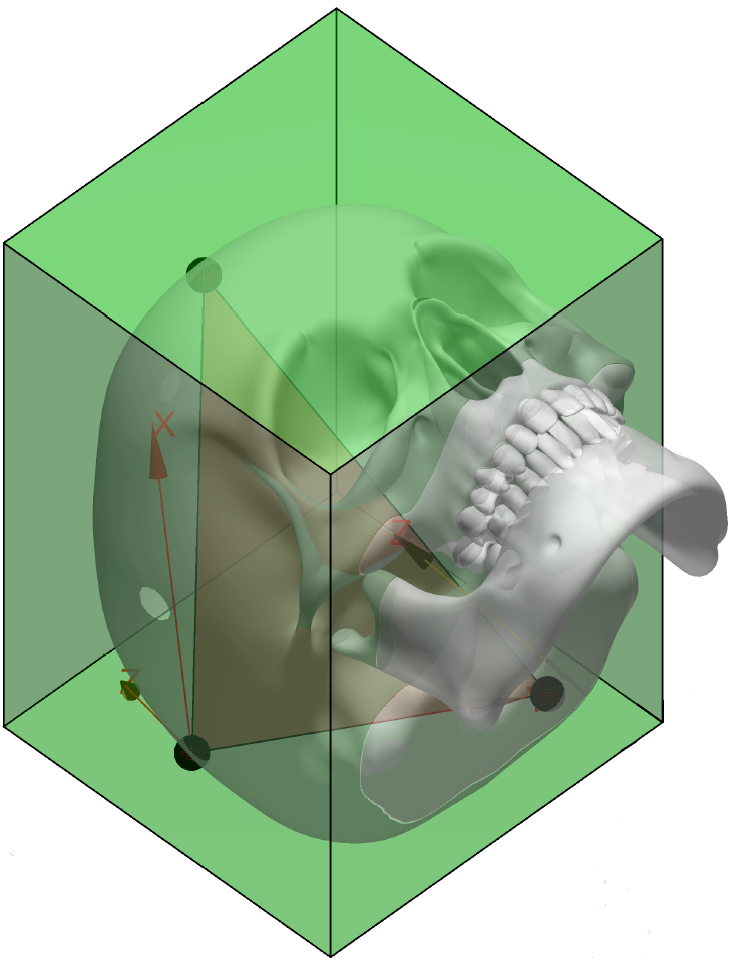

## put your code Here

hold on
%MAXIMOS DICOM [0-MAX]
maxDicomX = 222

maxDicomX = 222

maxDicomY = 256

maxDicomY = 256

maxDicomZ = 112*1.4

maxDicomZ = 156.8000


%CENTRO CALAVERA
centerSkullX = minX + ((maxX-minX)/2)

centerSkullX = 0.5383

centerSkullY = minY + ((maxY-minY) / 2)

centerSkullY = 1.0597

centerSkullZ = minZ + ((maxZ-minZ) / 2)

centerSkullZ = 0.1423


centerSkull = [centerSkullX, centerSkullY, centerSkullZ]

centerSkull =     0.5383    1.0597    0.1423



%CAJA CALAVERA DICOM
minXDic = 41

minXDic = 41

maxXDic = 206

maxXDic = 206

minYDic = 27

minYDic = 27

maxYDic = 234

maxYDic = 234

minZDic = 0

minZDic = 0

maxZDic = 122 * 1.4

maxZDic = 170.8000


maxDic = [maxXDic, maxYDic, maxZDic];
maxDic(:,4) = 1;
maxDic = trotz(pi) * maxDic';
maxDic = maxDic(1:3,:);

maxXDic = maxDic(1);
maxYDic = maxDic(2);
maxZDic = maxDic(3);

minDic = [minXDic, minYDic, minZDic];
minDic(:,4) = 1;
minDic = trotz(pi) * minDic';
minDic = minDic(1:3,:);

minXDic = minDic(1);
minYDic = minDic(2);
minZDic = minDic(3);
% pFid1(:,4) = 1;
% Vs2 = trotz(pi) * Vs';
% Vs2 = Vs2(1:3,:)'

%FIDUCIALS
pFid1 = [122, 61 , 131.6];
%pFid1(:,4) = 1;
%pFid1 = trotz(pi) * pFid1';
%pFid1 = pFid1(1:3,:)';

pFid2 = [185, 209 , 91]

pFid2 =    185   209    91


%pFid2(:,4) = 1;
%pFid2 = trotz(pi) * pFid2';
%pFid2 = pFid2(1:3,:)';

pFid3 = [71, 212 , 44.8]

pFid3 =    71.0000  212.0000   44.8000


%pFid3(:,4) = 1;
%pFid3 = trotz(pi) * pFid3';
%pFid3 = pFid3(1:3,:)';

%DIBUJO CAJA CEREBRO DICOM SPACE
hold on
v2= [minXDic minYDic minZDic;maxXDic minYDic minZDic;maxXDic maxYDic minZDic;minXDic maxYDic minZDic;minXDic minYDic maxDicomZ;maxXDic minYDic maxDicomZ;maxXDic maxYDic maxDicomZ;minXDic maxYDic maxDicomZ]

v2 =   -41.0000  -27.0000         0
 -206.0000  -27.0000         0
 -206.0000 -234.0000         0
  -41.0000 -234.0000         0
  -41.0000  -27.0000  156.8000
 -206.0000  -27.0000  156.8000
 -206.0000 -234.0000  156.8000
  -41.0000 -234.0000  156.8000


f2 = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f2 =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8




%patch('Vertices',v2,'Faces',f2,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)
%scatter3(pFid1(1), pFid1(2) ,pFid1(3))
%scatter3(pFid2(1), pFid2(2) ,pFid2(3))
%scatter3(pFid3(1), pFid3(2) ,pFid3(3))

axis equal

%CENTRO DICOM
centerDicomX = minXDic + ((maxXDic - minXDic) / 2);
centerDicomY = minYDic + (maxYDic - minYDic) / 2

centerDicomY = -130.5000

centerDicomZ = minZDic + (maxZDic - minZDic) / 2

centerDicomZ = 85.4000

centerDicom = [centerDicomX, centerDicomY, centerDicomZ]

centerDicom =  -123.5000 -130.5000   85.4000


centerDicom(:,4) = 1;
centerDicom = trotz(pi) * centerDicom';
centerDicom = centerDicom(1:3,:)';

%DIFERENCIA ENTRE CENTROS
difCenterDicSkl = centerDicom - centerSkull

difCenterDicSkl =   122.9617  129.4403   85.2577


pFid1Dif = pFid1 - difCenterDicSkl

pFid1Dif =    -0.9617  -68.4403   46.3423


pFid2Dif = pFid2 - difCenterDicSkl

pFid2Dif =    62.0383   79.5597    5.7423


pFid3Dif = pFid3 - difCenterDicSkl

pFid3Dif =   -51.9617   82.5597  -40.4577



hold on
%scatter3(pFid1(1),pFid1(2),pFid1(3))
%scatter3(pFid2(1),pFid2(2),pFid2(3))
%scatter3(pFid3(1),pFid3(2),pFid3(3))

%scatter3(pFid1Dif(1),pFid1Dif(2),pFid1Dif(3))
%scatter3(pFid2Dif(1),pFid2Dif(2),pFid2Dif(3))
%scatter3(pFid3Dif(1),pFid3Dif(2),pFid3Dif(3))
v= [minX minY minZ;maxX minY minZ;maxX maxY minZ;minX maxY minZ;minX minY maxZ;maxX minY maxZ;maxX maxY maxZ;minX maxY maxZ]

v =     1.0000    2.0000    0.0720
    0.0765    2.0000    0.0720
    0.0765    0.1194    0.0720
    1.0000    0.1194    0.0720
    1.0000    2.0000    0.2127
    0.0765    2.0000    0.2127
    0.0765    0.1194    0.2127
    1.0000    0.1194    0.2127


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


%patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)
light('Position',[1 1 1]);

dicomToSkullX = (maxX - minX) / (maxXDic - minXDic)

dicomToSkullX = 0.0056

dicomToSkullY = (maxY - minY) / (maxYDic - minYDic)

dicomToSkullY = 0.0091

dicomToSkullZ = (maxZ - minZ) / (maxZDic - minZDic)

dicomToSkullZ = 8.2350e-04

dicomToSkull = [dicomToSkullX ,dicomToSkullY, dicomToSkullZ]

dicomToSkull =     0.0056    0.0091    0.0008


%pFid1Aux = (pFid1 .* dicomToSkull)
%pFid2Aux = (pFid2 .* dicomToSkull)
%pFid3Aux = (centerSkull + (pFid3 .* dicomToSkull) / 2)

%scatter3(pFid1Aux(1),pFid1Aux(2),pFid1Aux(3))
%scatter3(pFid2Aux(1),pFid2Aux(2),pFid2Aux(3))
%scatter3(pFid3Aux(1),pFid3Aux(2),pFid3Aux(3))

%DICOM * PROP DICOM->SKULL
centerDicSk = centerDicom .* dicomToSkull

centerDicSk =     0.6912    1.1856    0.0703


pFid1S = pFid1 .* dicomToSkull

pFid1S =     0.6828    0.5542    0.1084


pFid2S = pFid2 .* dicomToSkull

pFid2S =     1.0354    1.8987    0.0749


pFid3S = pFid3 .* dicomToSkull

pFid3S =     0.3974    1.9260    0.0369



difCentDicSk2 = centerDicSk - centerSkull

difCentDicSk2 =     0.1530    0.1259   -0.0720



pFid1S = pFid1S - difCentDicSk2

pFid1S =     0.5299    0.4283    0.1804


pFid2S = pFid2S - difCentDicSk2

pFid2S =     0.8825    1.7729    0.1469


pFid3S = pFid3S - difCentDicSk2

pFid3S =     0.2444    1.8001    0.1089


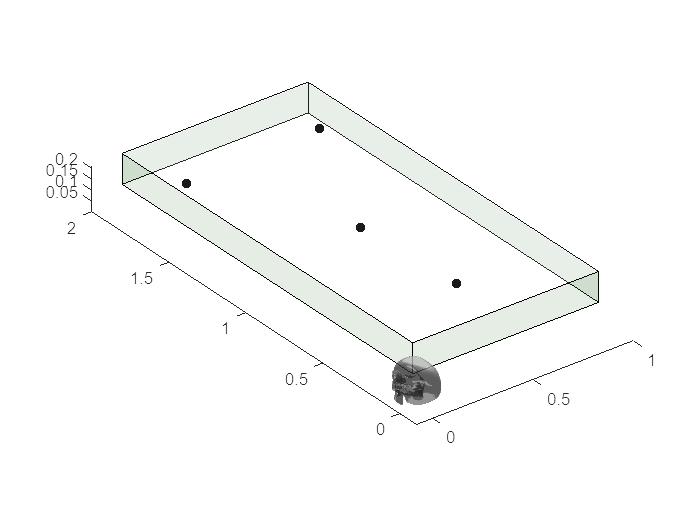

hold on
scatter3(pFid1S(1),pFid1S(2),pFid1S(3),'filled','MarkerFaceColor',[0 0 0])
scatter3(pFid2S(1),pFid2S(2),pFid2S(3),'filled','MarkerFaceColor',[0 0 0])
scatter3(pFid3S(1),pFid3S(2),pFid3S(3),'filled','MarkerFaceColor',[0 0 0])
scatter3(centerSkullX,centerSkullY,centerSkullZ,'filled','MarkerFaceColor',[0 0 0])

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

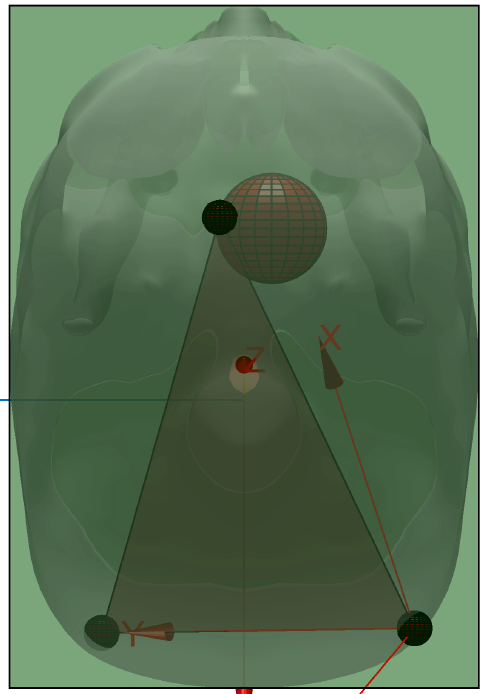

## put your code Here

hold on
v2= [minXDic minYDic minZDic;maxXDic minYDic minZDic;maxXDic maxYDic minZDic;minXDic maxYDic minZDic;minXDic minYDic maxDicomZ;maxXDic minYDic maxDicomZ;maxXDic maxYDic maxDicomZ;minXDic maxYDic maxDicomZ]

v2 =   -41.0000  -27.0000         0
 -206.0000  -27.0000         0
 -206.0000 -234.0000         0
  -41.0000 -234.0000         0
  -41.0000  -27.0000  156.8000
 -206.0000  -27.0000  156.8000
 -206.0000 -234.0000  156.8000
  -41.0000 -234.0000  156.8000


f2 = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f2 =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8



%hold on
%patch('Vertices',v2,'Faces',f2,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)
%scatter3(pFid1(1), pFid1(2) ,pFid1(3))
%scatter3(pFid2(1), pFid2(2) ,pFid2(3))
%scatter3(pFid3(1), pFid3(2) ,pFid3(3))
axis equal

tumorMaxZ = 90*1.4

tumorMaxZ = 126.0000

tumorMinZ = 64*1.4

tumorMinZ = 89.6000


tumorMaxX = 148

tumorMaxX = 148

tumorMinX = 113

tumorMinX = 113


tumorMaxY = 115

tumorMaxY = 115

tumorMinY = 80

tumorMinY = 80


difTZ = tumorMaxZ - tumorMinZ

difTZ = 36.4000

difTX = tumorMaxX - tumorMinX

difTX = 35

difTY = tumorMaxY - tumorMinY

difTY = 35


radioTumor = ((difTZ + difTY + difTX) / 3) / 2

radioTumor = 17.7333


tumorCenterDicomX = tumorMinX + difTX/2

tumorCenterDicomX = 130.5000

tumorCenterDicomY = tumorMinY + difTY/2

tumorCenterDicomY = 97.5000

tumorCenterDicomZ = tumorMinZ + difTZ/2

tumorCenterDicomZ = 107.8000


tumorCenterDicom = [tumorCenterDicomX,tumorCenterDicomY,tumorCenterDicomZ]

tumorCenterDicom =   130.5000   97.5000  107.8000



tumorCenterDicomSk = tumorCenterDicom .* dicomToSkull

tumorCenterDicomSk =     0.7304    0.8858    0.0888


tumorCenterDicomSk = tumorCenterDicomSk - difCentDicSk2

tumorCenterDicomSk =     0.5774    0.7599    0.1608



hold on
% Make unit sphere
[x,y,z] = sphere;
% Scale to desire radius.
radius = [radioTumor * dicomToSkullX,radioTumor * dicomToSkullX, radioTumor * dicomToSkullX];
x = x * radius(1);
y = y * radius(2);
z = z * radius(3);
% Translate sphere to new location.
offsetx = tumorCenterDicomX * dicomToSkullX - difCentDicSk2(1)

offsetx = 0.5774

offsety = tumorCenterDicomY * dicomToSkullY - difCentDicSk2(2)

offsety = 0.7599

offsetz = tumorCenterDicomZ * dicomToSkullZ - difCentDicSk2(3)

offsetz = 0.1608

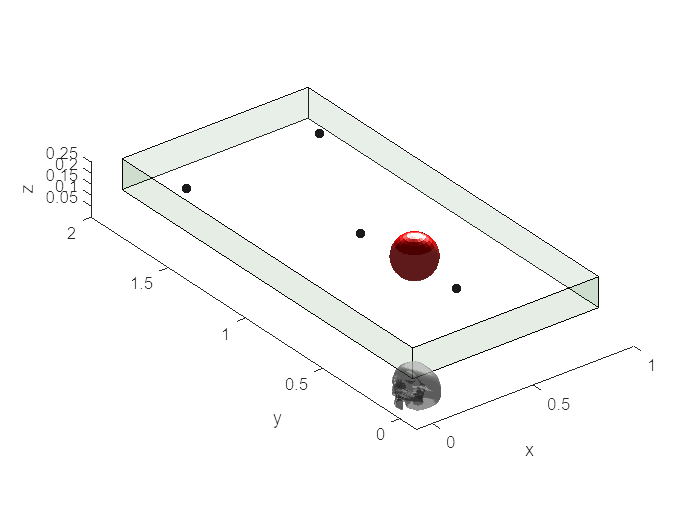

% Plot as surface.
surf(x+offsetx,y+offsety,z+offsetz,'FaceColor','r','EdgeColor','none')
axis equal;
xyzlabel

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. You will have to re-do the containing box secction.

**Expected results**

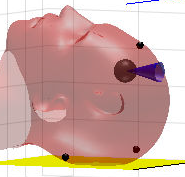

maxXBody = 2.25

maxXBody = 2.2500

minXBody = 2.09

minXBody = 2.0900


maxYBody = 0.45

maxYBody = 0.4500

minYBody = 0.30

minYBody = 0.3000


maxZBody = 0.87

maxZBody = 0.8700

minZBody = 0.665

minZBody = 0.6650

centerBody = [(minXBody + (maxXBody-minXBody)/2 ),(minYBody + (maxYBody-minYBody)/2),(minZBody + (maxZBody-minZBody)/2)]

centerBody =     2.1700    0.3750    0.7675


%TABLE
clf
minXMesa = 0

minXMesa = 0

minYMesa = 0

minYMesa = 0

maxXMesa = 2

maxXMesa = 2

maxYMesa = 0.75

maxYMesa = 0.7500

minZMesa = 0.5

minZMesa = 0.5000

maxZMesa = 0.6

maxZMesa = 0.6000

v = [minXMesa minYMesa minZMesa; minXMesa maxYMesa minZMesa; maxXMesa maxYMesa minZMesa; maxXMesa minYMesa minZMesa;minXMesa minYMesa maxZMesa; minXMesa maxYMesa maxZMesa; maxXMesa maxYMesa maxZMesa; maxXMesa minYMesa maxZMesa];
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
view(3)
patch('Faces',f,'Vertices',v,'FaceColor',[0 0.5 0])
r = 0.02;
[X,Y,Z] = cylinder(r);
h = 0.6;
Z = Z*h-0.01;
hold on
surf(X+0.1,Y+0.1,Z)
surf(X+0.1,Y+0.65,Z)
surf(X+1.9,Y+0.1,Z)
surf(X+1.9,Y+0.65,Z)

axis equal
% HUMAN
load('F_V_HumanBody.mat')
view(3)
Vh(:,4) = 1;
Vh1 = transl(0.45,0.375,0.77)*trotz(-pi/2)*trotx(-pi/2)*Vh'

Vh1 =     1.7610    1.7649    1.7738    1.7706    1.7789    1.7786    1.7805    1.7844    1.7881    1.7919    1.7961    1.8000    1.7864    1.7948    1.7972    1.8035    1.8068    1.8125    1.8165    1.8214    1.8262    1.8301    1.8359    1.8312    1.8206    1.8419    1.8245    1.8316    1.8383    1.8167    1.8452    1.8084    1.8042    1.8121    1.8100    1.7996    1.7909    1.7894    1.8019    1.7879    1.7792    1.7787    1.7799    1.8131    1.8159    1.8039    1.7922    1.7693    1.7580    1.7589
    0.4893    0.5018    0.4941    0.4857    0.4896    0.4833    0.4987    0.4912    0.5016    0.4930    0.5037    0.4948    0.4831    0.4840    0.4743    0.4853    0.4753    0.4869    0.4768    0.4889    0.4789    0.4912    0.4814    0.4684    0.4663    0.4710    0.5003    0.5027    0.4941    0.4983    0.4846    0.4965    0.5054    0.5068    0.4649    0.4640    0.4530    0.4637    0.4532    0.4739    0.4641    0.4743    0.4533    0.4541    0.4432    0.4425    0.4422    0.4759    0.4667   

minCuerpo = min(Vh)

minCuerpo =    -0.5083   -0.1668   -0.0049    1.0000


minCuerpoX = minCuerpo(1);
minCuerpoY = minCuerpo(2);
minCuerpoZ = minCuerpo(3);

patch('Vertices',Vh1(1:3,:)','Faces',Fh,'FaceColor', [0.82 0.64 0.52], 'EdgeColor' , 'none', 'FaceAlpha', 0.6)
axis equal
light('Position',[20 20 20]);
view([-29.413 89.040])
%DIBUJO CAJA HEAD IN WORLD SPACE
hold on
v3= [minXBody minYBody minZBody;maxXBody minYBody minZBody;maxXBody maxYBody minZBody;minXBody maxYBody minZBody;minXBody minYBody maxZBody;maxXBody minYBody maxZBody;maxXBody maxYBody maxZBody;minXBody maxYBody maxZBody]

v3 =     2.0900    0.3000    0.6650
    2.2500    0.3000    0.6650
    2.2500    0.4500    0.6650
    2.0900    0.4500    0.6650
    2.0900    0.3000    0.8700
    2.2500    0.3000    0.8700
    2.2500    0.4500    0.8700
    2.0900    0.4500    0.8700


f3 = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f3 =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


patch('Vertices',v3,'Faces',f3,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)

%PROP Craneo-Cabeza
skullToHeadX = (maxXBody - minXBody) / (maxX - minX)

skullToHeadX = -0.1733

skullToHeadY = (maxYBody - minYBody) / (maxY - minY)

skullToHeadY = -0.0798

skullToHeadZ = (maxZBody - minZBody) / (maxZ - minZ)

skullToHeadZ = 1.4575

skullToHead = [skullToHeadX,skullToHeadY,skullToHeadZ]

skullToHead =    -0.1733   -0.0798    1.4575


centerSkull

centerSkull =     0.5383    1.0597    0.1423


% centerSkull = [0,0,0];
% centerSkull(:,4) = 1;
% centerSkull = troty(pi/2)*trotz(pi/2) * centerSkull';
% centerSkull = centerSkull(1:3,:)';
centerSkullBody = centerSkull .* skullToHead

centerSkullBody =    -0.0933   -0.0845    0.2074


% centerSkullBody(:,4) = 1;
% centerSkullBody = troty(pi/2)*trotz(pi/2) * centerSkullBody';
% centerSkullBody = centerSkullBody(1:3,:)';
disSkullBody = centerBody - centerSkullBody

disSkullBody =     2.2633    0.4595    0.5601



centerSkullBody = centerSkullBody + disSkullBody

centerSkullBody =     2.1700    0.3750    0.7675



% scatter3(centerSkullBody(1),centerSkullBody(2),centerSkullBody(3),'filled','MarkerFaceColor',[1 0 0])


%scatter3(centerBody(1),centerBody(2),centerBody(3),'filled','MarkerFaceColor',[0 0 0])


pFid1Head = pFid1S .* skullToHead

pFid1Head =    -0.0918   -0.0342    0.2629


pFid2Head = pFid2S .* skullToHead

pFid2Head =    -0.1529   -0.1414    0.2142


pFid3Head = pFid3S .* skullToHead

pFid3Head =    -0.0423   -0.1436    0.1587



pFid1Head = pFid1Head + disSkullBody

pFid1Head =     2.1715    0.4254    0.8230


% pFid1Head(:,4) = 1;
% pFid1Head = transl(0) * trotz(pi/2)* troty(pi/2) * pFid1Head';
% pFid1Head = pFid1Head(1:3,:)';

pFid2Head = pFid2Head + disSkullBody

pFid2Head =     2.1104    0.3181    0.7742


% pFid2Head(:,4) = 1;
% pFid2Head = transl(0) *troty(pi/2)*trotz(pi/2) * pFid2Head';
% pFid2Head = pFid2Head(1:3,:)';

pFid3Head = pFid3Head + disSkullBody

pFid3Head =     2.2209    0.3159    0.7188


% pFid3Head(:,4) = 1;
% pFid3Head = transl(0) *troty(pi/2)*trotz(pi/2) * pFid3Head';
% pFid3Head = pFid3Head(1:3,:)';

pFid1Head = pFid1Head - centerBody

pFid1Head =     0.0015    0.0504    0.0555


pFid1Head(:,4) = 1;
pFid1Head = transl(0)*trotz(pi/2)*trotx(pi/2) * trotz(0)* troty(0) * pFid1Head';
pFid1Head = pFid1Head(1:3,:)';
pFid1Head = pFid1Head + centerBody

pFid1Head =     2.2255    0.3765    0.8179



pFid2Head = pFid2Head - centerBody

pFid2Head =    -0.0596   -0.0569    0.0067


pFid2Head(:,4) = 1;
pFid2Head = transl(0)*trotz(pi/2)*trotx(pi/2) *troty(0)*trotz(0) * pFid2Head';
pFid2Head = pFid2Head(1:3,:)';
pFid2Head = pFid2Head + centerBody

pFid2Head = 1×3
    2.1767    0.3154    0.7106



pFid3Head = pFid3Head - centerBody

pFid3Head = 1×3
    0.0509   -0.0591   -0.0487


pFid3Head(:,4) = 1;
pFid3Head = transl(0)*trotz(pi/2)*trotx(pi/2) * pFid3Head';
pFid3Head = pFid3Head(1:3,:)';
pFid3Head = pFid3Head + centerBody

pFid3Head = 1×3
    2.1213    0.4259    0.7084



scatter3(pFid1Head(1), pFid1Head(2) ,pFid1Head(3),'MarkerFaceColor',[0 0 0])
scatter3(pFid2Head(1), pFid2Head(2) ,pFid2Head(3),'MarkerFaceColor',[0 0 0])
scatter3(pFid3Head(1), pFid3Head(2) ,pFid3Head(3),'MarkerFaceColor',[0 0 0])
xyzlabel

%TUMOR

tumorBody = tumorCenterDicomSk .* skullToHead

tumorBody = 1×3
   -0.1000   -0.0606    0.2343


tumorBody = tumorBody + disSkullBody

tumorBody = 1×3
    2.1632    0.3989    0.7944


tumorBody = tumorBody - centerBody

tumorBody = 1×3
   -0.0068    0.0239    0.0269


tumorBody(:,4) = 1;
tumorBody = transl(0)*trotz(pi/2)*trotx(pi/2) * trotz(0)* troty(0) * tumorBody';
tumorBody = tumorBody(1:3,:)';
tumorBody = tumorBody + centerBody

tumorBody = 1×3
    2.1969    0.3682    0.7914




% pFid1Head = pFid1S .* skullToHead
% pFid1Head = pFid1Head + disSkullBody
% pFid1Head = pFid1Head - centerBody
% pFid1Head(:,4) = 1;
% pFid1Head = transl(0)*trotz(pi/2)*trotx(pi/2) * trotz(0)* troty(0) * pFid1Head';
% pFid1Head = pFid1Head(1:3,:)';
% pFid1Head = pFid1Head + centerBody

% Make unit sphere
[x,y,z] = sphere;
% Scale to desire radius.
radius = [radioTumor * dicomToSkullX * skullToHeadX,radioTumor * dicomToSkullX * skullToHeadX, radioTumor * dicomToSkullX * skullToHeadX];
x = x * radius(1);
y = y * radius(2);
z = z * radius(3);
% Translate sphere to new location.
offsetx = tumorBody(1)

offsetx = 2.1969

offsety = tumorBody(2)

offsety = 0.3682

offsetz = tumorBody(3)

offsetz = 0.7914

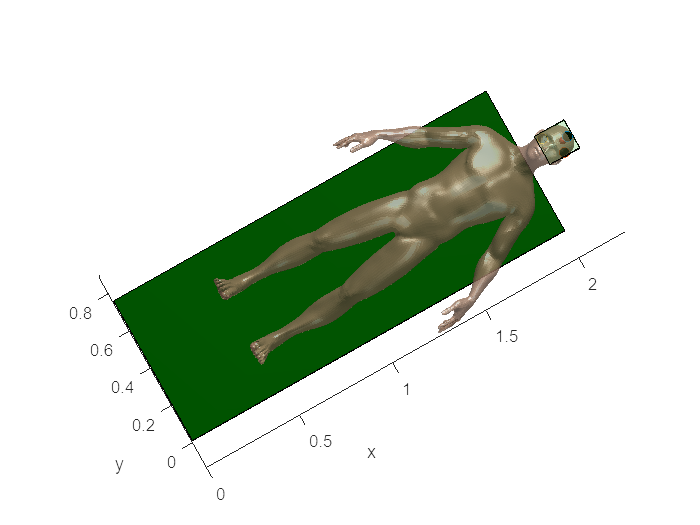

% Plot as surface.
surf(x+offsetx,y+offsety,z+offsetz,'FaceColor','r','EdgeColor','none')
axis equal;
xyzlabel

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

**Expected results**

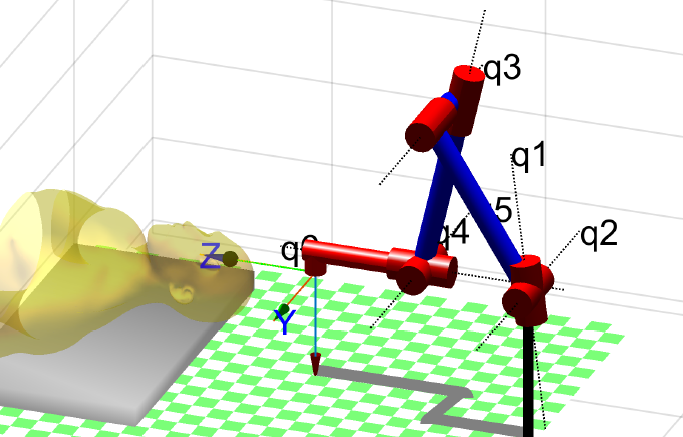

## put your code Here

mdl_puma560;
p560.base=transl(centerBody(1) + 0.65,centerBody(2),0.9)*trotz(pi)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (2.82, 0.375, 0.9), RPY/xyz = (-180, 0, 0) deg      
 


hold on;
%p560.plot(qr,'zoom',1.5)
T_R_U=p560.base.T

T_R_U =    -1.0000         0         0    2.8200
         0   -1.0000         0    0.3750
         0         0    1.0000    0.9000
         0         0         0    1.0000


hold on;
p560.tool = troty(pi)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (2.82, 0.375, 0.9), RPY/xyz = (-180, 0, 0) deg      
tool:    t = (0, 0, 0), RPY/xyz = (-180, 0, -180) deg            
 


T_P_U = p560.tool.T 

T_P_U =     -1     0     0     0
     0     1     0     0
     0     0    -1     0
     0     0     0     1


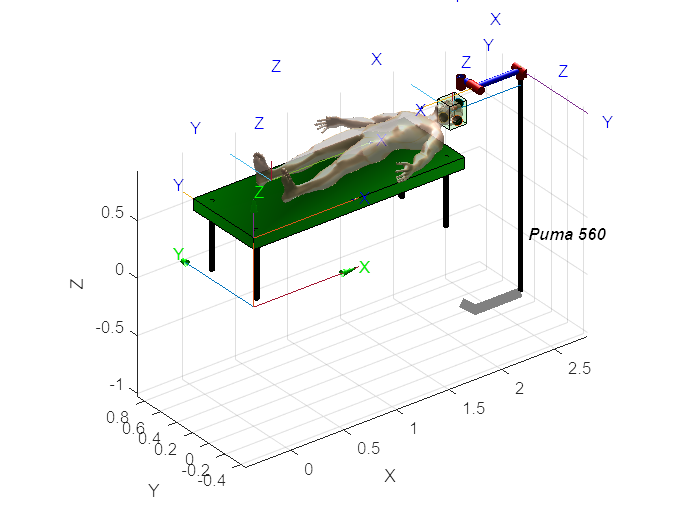

p560.plot(qz,'zoom',1.5,'notiles');% RTB

p560.base.plot()

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...

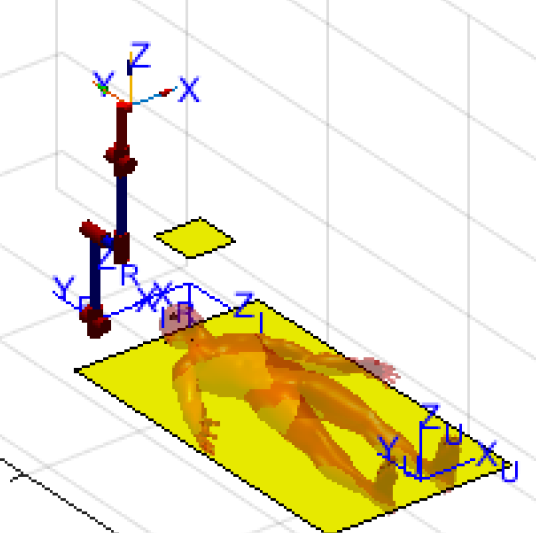

hold on;
T_U = transl(0)

T_U = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


trplot(T_U,'framelabel','B','color','g','arrow','width',1)
trplot(T_R_U,'framelabel','B' ,'color', 'b','arrow','width',0.4)
T_H_U = transl(centerBody(1),centerBody(2),centerBody(3))*trotz(pi/2)*trotx(pi/2) * trotz(0);
trplot(T_H_U,'framelabel','B' ,'color', 'b','arrow','width',0.4)
T_M_U = transl(minXMesa,minYMesa,maxZMesa);
trplot(T_M_U,'framelabel','B' ,'color', 'b','arrow','width',0.4)
%  TRANS BODY 0.45,0.375,0.77
T_B_U = transl(0.45,0.375,0.77);
trplot(T_B_U,'framelabel','B' ,'color', 'b','arrow','width',0.4)

### Transformations

Enumerate the transformation you will need.

%% put your code Here

### Tumor points in Robot Frame.

Remember the Transform compound exercise

%% put your code Here


## *Second approach: ( 25%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ , ‘5_Skull_pose estimation.mlx’ for inspiration and Second_approach_SPM.pdf*

open('3_Second_approach_Patient_pose.fig')

## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0.05 0 0.25)

Let us see the 'trail' option of plot to visualize the trajectory.

%% put your code Here

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0 0 0.2)

Let us see the 'trail' option of plot to visualize the trajectory. Place a 45º cone on top of the trepanation to better understand. See: 6_Plot_Box_Cone.mlx. You will have to scale it. Play with transparency.

%% put your code Here

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4m diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

%% put your code Here